dbstop if error;
addpath(genpath('./dlt_cnn_map_dropout_nobiasnn'));
rand('state', 11);

## Load data

dataset = 'mnist';
if strcmp(dataset, 'mnist') == 1
    load mnist_uint8;
    train_x = double(reshape(train_x',28,28,60000))/255;
    test_x = double(reshape(test_x',28,28,10000))/255;
    train_y = double(train_y');
    test_y = double(test_y');
elseif strcmp(dataset, 'fashion_mnist') == 1
    train_images = loadMNISTImages('train-images-idx3-ubyte');
    train_labels = loadMNISTLabels('train-labels-idx1-ubyte');
    train_x = double(reshape(train_images, 28, 28, 60000));
    train_y = zeros(10, 60000);
    for i = 1 : 60000
        train_y(train_labels(i)+1, i) = 1;
    end
    test_images = loadMNISTImages('t10k-images-idx3-ubyte');
    test_labels = loadMNISTLabels('t10k-labels-idx1-ubyte');
    test_x = double(reshape(test_images, 28, 28, 10000));
    test_y = zeros(10, 10000);
    for i = 1 : 10000
        test_y(test_labels(i)+1, i) = 1;
    end
end
 
% train_x = train_x(:,:,1:50000);
% train_y = train_y(:,1:50000);
% test_x = test_x(:,:,1:1000);
% test_y = test_y(:,1:1000);

## Noise

% noise_type = 'none';
% snr = '-3db';
% train_x = makenoise(train_x, noise_type, snr);
% test_x = makenoise(test_x, noise_type, snr);

## Initialize net

train_new_model = 0;
if train_new_model == 1
    cnn.layers = {
        struct('type', 'i') %input layer
        struct('type', 'c', 'outputmaps', 48, 'kernelsize', 5) %convolution layer, 32 x 24 x 24
        struct('type', 's', 'scale', 2) %sub sampling layer, 32 x 12 x 12
        struct('type', 'c', 'outputmaps', 96, 'kernelsize', 5) %convolution layer, 64 x 10 x 10
        struct('type', 's', 'scale', 2) %subsampling layer
%         struct('type', 'c', 'outputmaps', 128, 'kernelsize', 3) %convolution layer, 128 x 8 x 8
%         struct('type', 's', 'scale', 2) %subsampling layer, 128 x 4 x 4
    };
    cnn = cnnsetup(cnn, train_x, train_y);
    % Set the activation function to be a ReLU
    cnn.act_fun = @(inp)max(0, inp);
    % Set the derivative to be the binary derivative of a ReLU
    cnn.d_act_fun = @(forward_act)double(forward_act>0);
    opts.alpha = 0.1;
    opts.batchsize = 100;
    opts.numepochs =  20;    
    opts.learn_bias = 0;
    opts.dropout = 0.1;
    cnn.first_layer_dropout = 0;
    % Train - takes about 199 seconds per epoch on my machine

    cnn = cnntrain(cnn, train_x, train_y, opts);
    % Test
    [er, bad] = cnntest(cnn, train_x, train_y);
    % fprintf('TRAINING Accuracy: %2.2f%%.\n', (1-er)*100);
    [er, bad] = cnntest(cnn, test_x, test_y);
    fprintf('Test Accuracy: %2.2f%%.\n', (1-er)*100);
else
    if strcmp(dataset, 'mnist') == 1
        load cnn_mnist_99.14.mat;
    else
        load fashion_mnist_cnn.mat;
    end
    [er, bad] = cnntest(cnn, test_x, test_y);
    fprintf('Test Accuracy: %2.2f%%.\n', (1-er)*100);
end

Test Accuracy: 98.70%.


## Spike-based Testing of a ConvNet

### **Pure Spiking CNN**

t_opts = struct('t_ref', 0.000, 'threshold', 2.0, 'dt', 0.001, 'duration', 0.200, 'report_every', 0.001, 'max_rate', 500);
SCNN = convlifsim(cnn, test_x, test_y, t_opts);

.............................................
No IP: Time: 0.001s | Accuracy: 9.20%.
No IP: Time: 0.002s | Accuracy: 9.20%.
No IP: Time: 0.003s | Accuracy: 9.20%.
No IP: Time: 0.004s | Accuracy: 9.20%.
No IP: Time: 0.005s | Accuracy: 9.20%.
No IP: Time: 0.006s | Accuracy: 9.20%.
No IP: Time: 0.007s | Accuracy: 9.20%.
No IP: Time: 0.008s | Accuracy: 9.20%.
No IP: Time: 0.009s | Accuracy: 9.20%.
No IP: Time: 0.010s | Accuracy: 9.20%.
No IP: Time: 0.011s | Accuracy: 9.20%.
No IP: Time: 0.012s | Accuracy: 9.20%.
No IP: Time: 0.013s | Accuracy: 9.20%.
No IP: Time: 0.014s | Accuracy: 9.20%.
No IP: Time: 0.015s | Accuracy: 9.20%.
No IP: Time: 0.016s | Accuracy: 9.20%.
No IP: Time: 0.017s | Accuracy: 9.20%.
No IP: Time: 0.018s | Accuracy: 9.20%.
No IP: Time: 0.019s | Accuracy: 9.20%.
No IP: Time: 0.020s | Accuracy: 9.20%.
No IP: Time: 0.021s | Accuracy: 9.20%.
No IP: Time: 0.022s | Accuracy: 9.20%.
No IP: Time: 0.023s | Accuracy: 9.20%.
No IP: Time: 0.024s | Accuracy: 9.20%.
No IP: Time: 0.025

### Spiking CNN with Intrinsic Plasticity

ip_opts = struct('tau', 0.1, 'sigma', 0.5, 'beta', 0.6, 'learning_rate', 1, 'initial_rC', 2, 'initial_rR', 2);
SCNN_IP = convlifsim_ip(cnn, test_x, test_y, t_opts, ip_opts);

regular IP: Time: 0.001s | Accuracy: 9.20%.
regular IP: Time: 0.002s | Accuracy: 9.20%.
regular IP: Time: 0.003s | Accuracy: 9.20%.
regular IP: Time: 0.004s | Accuracy: 9.20%.
regular IP: Time: 0.005s | Accuracy: 9.20%.
regular IP: Time: 0.006s | Accuracy: 9.20%.
regular IP: Time: 0.007s | Accuracy: 9.20%.
regular IP: Time: 0.008s | Accuracy: 9.20%.
regular IP: Time: 0.009s | Accuracy: 9.20%.
regular IP: Time: 0.010s | Accuracy: 9.20%.
regular IP: Time: 0.011s | Accuracy: 9.20%.
regular IP: Time: 0.012s | Accuracy: 9.20%.
regular IP: Time: 0.013s | Accuracy: 9.20%.
regular IP: Time: 0.014s | Accuracy: 9.20%.
regular IP: Time: 0.015s | Accuracy: 9.20%.
regular IP: Time: 0.016s | Accuracy: 9.20%.
regular IP: Time: 0.017s | Accuracy: 9.20%.
regular IP: Time: 0.018s | Accuracy: 9.20%.
regular IP: Time: 0.019s | Accuracy: 9.20%.
regular IP: Time: 0.020s | Accuracy: 9.20%.
regular IP: Time: 0.021s | Accuracy: 9.20%.
regular IP: Time: 0.022s | Accuracy: 9.20%.
regular IP: Time: 0.023s | Accur

### **Spiking CNN with Input-Driven Intrinsic Plasticity**

ip_opts = struct('tau', 0.1, 'sigma', 0.5, 'beta', 0.6, 'learning_rate', 1, 'initial_rC', 1, 'initial_rR', 2);
SCNN_INPUT_DRIVEN_IP = convlifsim_input_driven_ip(cnn, test_x, test_y, t_opts, ip_opts);

Input Driven IP: Time: 0.001s | Accuracy: 9.20%.
Input Driven IP: Time: 0.002s | Accuracy: 9.20%.
Input Driven IP: Time: 0.003s | Accuracy: 9.20%.
Input Driven IP: Time: 0.004s | Accuracy: 9.20%.
Input Driven IP: Time: 0.005s | Accuracy: 9.20%.
Input Driven IP: Time: 0.006s | Accuracy: 9.20%.
Input Driven IP: Time: 0.007s | Accuracy: 9.20%.
Input Driven IP: Time: 0.008s | Accuracy: 9.20%.
Input Driven IP: Time: 0.009s | Accuracy: 9.20%.
Input Driven IP: Time: 0.010s | Accuracy: 9.20%.
Input Driven IP: Time: 0.011s | Accuracy: 9.20%.
Input Driven IP: Time: 0.012s | Accuracy: 9.20%.
Input Driven IP: Time: 0.013s | Accuracy: 9.20%.
Input Driven IP: Time: 0.014s | Accuracy: 9.20%.
Input Driven IP: Time: 0.015s | Accuracy: 9.20%.
Input Driven IP: Time: 0.016s | Accuracy: 9.20%.
Input Driven IP: Time: 0.017s | Accuracy: 9.20%.
Input Driven IP: Time: 0.018s | Accuracy: 9.20%.
Input Driven IP: Time: 0.019s | Accuracy: 9.20%.
Input Driven IP: Time: 0.020s | Accuracy: 9.20%.
Input Driven IP: Tim

### **Spiking CNN with Self-Driven Intrinsic Plasticity**

ip_opts = struct('tau', 0.005, 'sigma', 0.5, 'beta', 0.6, 'learning_rate', 1, 'initial_rC', 1, 'initial_rR', 2);
SCNN_SELF_DRIVEN_IP = convlifsim_self_driven_ip(cnn, test_x, test_y, t_opts, ip_opts);

Self Driven IP: Time: 0.001s | Accuracy: 9.20%.
Self Driven IP: Time: 0.002s | Accuracy: 9.20%.
Self Driven IP: Time: 0.003s | Accuracy: 9.20%.
Self Driven IP: Time: 0.004s | Accuracy: 9.20%.
Self Driven IP: Time: 0.005s | Accuracy: 9.20%.
Self Driven IP: Time: 0.006s | Accuracy: 9.20%.
Self Driven IP: Time: 0.007s | Accuracy: 9.20%.
Self Driven IP: Time: 0.008s | Accuracy: 9.20%.
Self Driven IP: Time: 0.009s | Accuracy: 9.20%.
Self Driven IP: Time: 0.010s | Accuracy: 9.20%.
Self Driven IP: Time: 0.011s | Accuracy: 9.20%.
Self Driven IP: Time: 0.012s | Accuracy: 9.20%.
Self Driven IP: Time: 0.013s | Accuracy: 9.20%.
Self Driven IP: Time: 0.014s | Accuracy: 9.20%.
Self Driven IP: Time: 0.015s | Accuracy: 9.20%.
Self Driven IP: Time: 0.016s | Accuracy: 9.20%.
Self Driven IP: Time: 0.017s | Accuracy: 9.20%.
Self Driven IP: Time: 0.018s | Accuracy: 9.20%.
Self Driven IP: Time: 0.019s | Accuracy: 9.20%.
Self Driven IP: Time: 0.020s | Accuracy: 9.20%.
Self Driven IP: Time: 0.021s | Accuracy:

## Show the difference

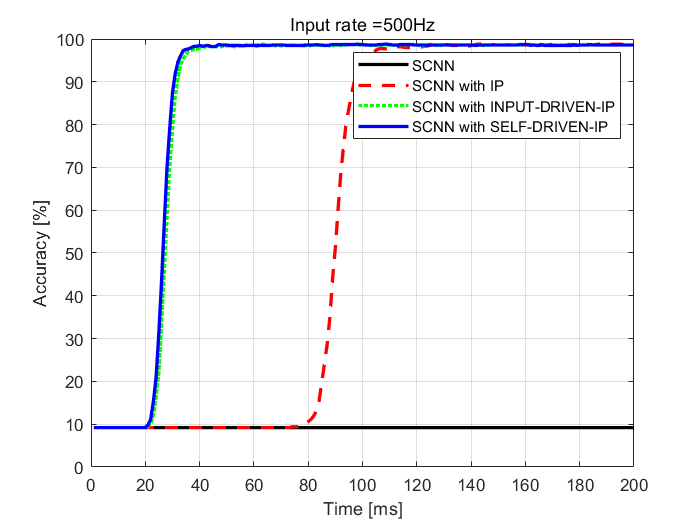

figure(); clf;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN.performance,'color','black','linewidth',2, 'LineStyle','-', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_IP.performance,'color',[1,0,0],'linewidth',2, 'LineStyle','--', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_INPUT_DRIVEN_IP.performance,'color',[0,1,0],'linewidth',2, 'LineStyle',':', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_SELF_DRIVEN_IP.performance,'color',[0,0,1],'linewidth',2, 'LineStyle','-', 'Marker','none');
legend('SCNN', 'SCNN with IP', 'SCNN with INPUT-DRIVEN-IP', 'SCNN with SELF-DRIVEN-IP');
ylim([00 100]);
xlabel('Time [ms]');
ylabel('Accuracy [%]');
title(strcat('Input rate = ', num2str(t_opts.max_rate), 'Hz'));
grid();

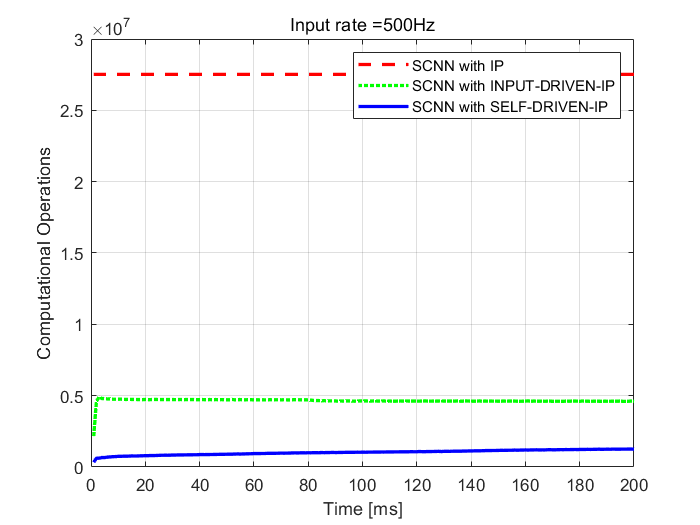

figure(); clf;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_IP.computational_operations,'color',[1,0,0],'linewidth',2, 'LineStyle','--', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_INPUT_DRIVEN_IP.computational_operations,'color',[0,1,0],'linewidth',2, 'LineStyle',':', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SCNN_SELF_DRIVEN_IP.computational_operations,'color',[0,0,1],'linewidth',2, 'LineStyle','-', 'Marker','none');
legend('SCNN with IP', 'SCNN with INPUT-DRIVEN-IP', 'SCNN with SELF-DRIVEN-IP');
xlabel('Time [ms]');
ylabel('Computational Operations');
title(strcat('Input rate = ', num2str(t_opts.max_rate), 'Hz'));
grid();